clf;

w = abs([1.206, -0.9207, 1.135, 1.66]);
k = [57.13,114.4,171.5,229];
neg = abs([(1.206-0.9226),(-0.9207--1.412),(1.135+0.4876),(1.66-0.3782)]);
pos = abs([(1.206-1.489),(-0.9207--0.229),(1.135-2.758),(1.66-3.698)]);

e = errorbar(k, w, neg, pos);
e.LineStyle = 'none';

hold on

[xData, yData] = prepareCurveData( k, w );
ft = fittype( 'poly3' );
[fitresult, gof] = fit( xData, yData, ft )

fitresult =      Linear model Poly3:
     fitresult(x) = p1*x^3 + p2*x^2 + p3*x + p4
     Coefficients:
       p1 =  -1.713e-07
       p2 =   0.0001352
       p3 =    -0.02424
       p4 =       2.182

gof = struct with fields:
           sse: 7.5065e-30
       rsquare: 1
           dfe: 0
    adjrsquare: NaN
          rmse: NaN


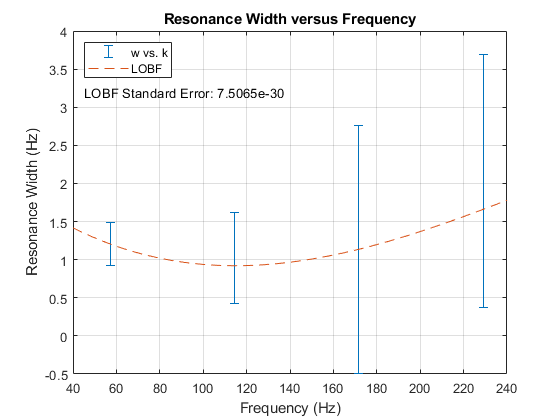


h = plot( fitresult, '--' );
legend( 'w vs. k', 'LOBF', 'Location', 'NorthWest' );


% Label axes
xlabel( 'Frequency (Hz)');
ylabel( 'Resonance Width (Hz)');
title( 'Resonance Width versus Frequency')

text(45,3.2,"LOBF Standard Error: " + string(gof.sse))

grid on
hold off